Setup

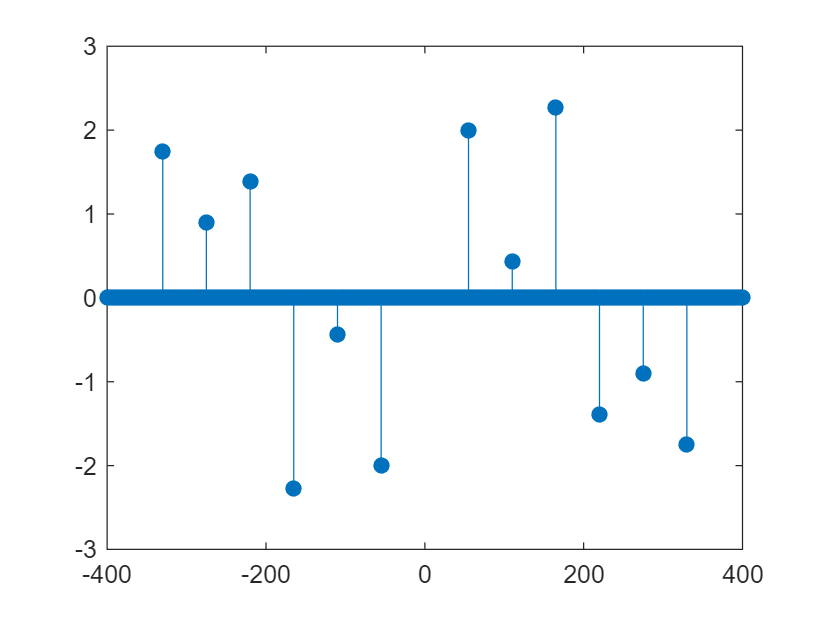

close all
clear

f = [112,168,224,283,336,450,505,566,672];
mag = [0.9,5,1.3,7,4,11.3,2.9,7.4,3.1]/10;
phase = [0.4392    2.2737   -1.3899   -0.9030   -1.7514    1.8965    2.9271  -0.1742    2.7301];


f = [55,110,165,220,275,330];
mag = [1.4 0.9,5,1.3,7,4]/30;
phase = [2, 0.4392    2.2737   -1.3899   -0.9030   -1.7514  ];

cn_pos = mag.*exp(1i*phase);


N = 400;
freq = -N:1:N;
cn = zeros(size(freq));
% bn = zeros(size(freq));

cn(N+1+f) = cn_pos;
cn(N-f+1) = cn_pos';



stem(freq,angle(cn),'Filled')

% First definition reconstruction
t = linspace(0,0.04,500);
ft = zeros(size(t));
L = 0.5;
n = freq;
for k = 1:numel(n)
    ft = ft + cn(k)*exp(1i*pi/L*n(k).*t);
end

colors=lines(10);

Time domain plot

% Time domain
figure
plot(t,ft)

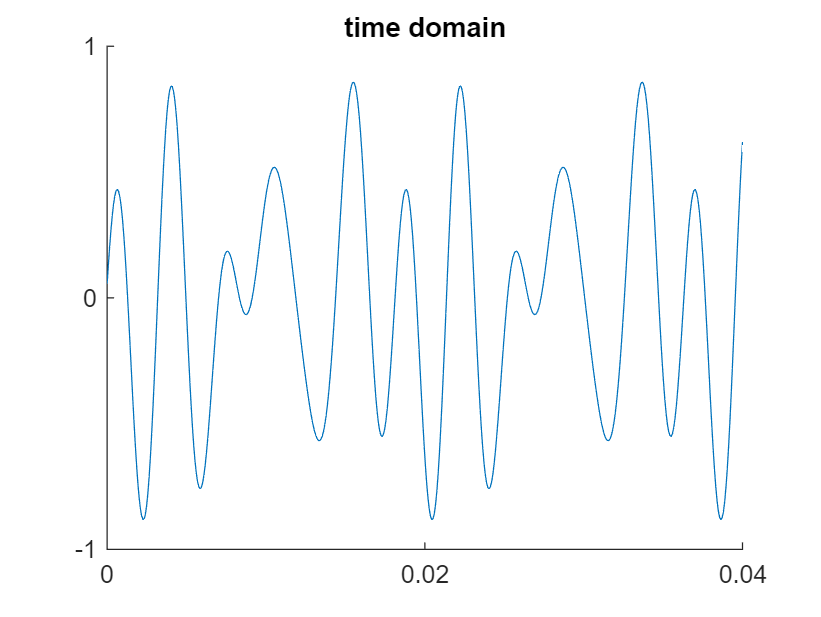

title("time domain")
axis tight
box off
ylim([-1,1])
xticks([0,0.02 0.04])
yticks([-1,0,1])

First definition coefficients

% % an bn plots
% figure
% 
% subplot(2,1,1)
% stem(freq,an,"filled",'color',colors(1,:))
% ylim([-4.5,4.5])
% yticks([-4,0,4])
% box off
% xticks([110,220,330,440,550])
% title('bn')
% 
% subplot(2,1,2)
% stem(freq,bn,"filled",'color',colors(2,:))
% ylim([-4.5,4.5])
% yticks([-4,0,4])
% title('an')
% box off
% xticks([110,220,330,440,550])

Second definition

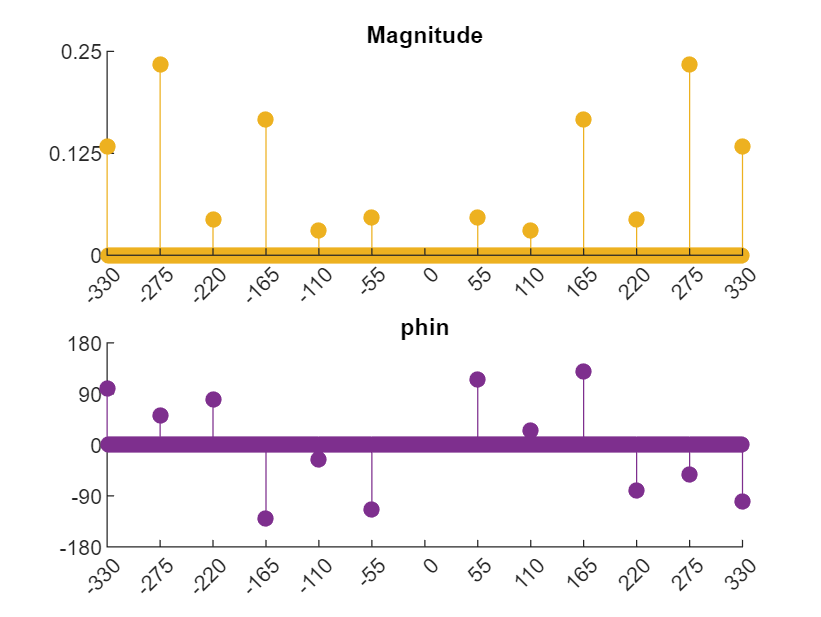

figure

subplot(2,1,1)
stem(freq,abs(cn),"filled",'color',colors(3,:))
xticks([110,220,330,440,550])
yticks([0,0.125,0.25])
ylim([0,0.25])
xticks([-f(end:-1:1),0,f])
xlim([-330,330])
box off
title('Magnitude')

subplot(2,1,2)
stem(freq,angle(cn)*180/(pi),"filled",'color',colors(4,:))
ylim([-180,180])
yticks([-180,-90,0,90,180])
title('phin')
xticks([-f(end:-1:1),0,f])
xlim([-330,330])
box off